
%#ok<*CLALL>

clear all;clc 

gridSettings = gridSettingsClass; 

gridSettings.gridSize = [16, 32]; 

% Let 1 tick be 6 hours. 
gridSettings.ticksPerYear = 365*24; 

gridSettings.tickSpan = 1 : gridSettings.ticksPerYear; 

gridSettings.riskFactorMean = -1E-3; 
gridSettings.riskFactorStandardDeviation = 1E-3; 
gridSettings.riskFactorAmplitudeMean = 1E-3; 
gridSettings.riskFactorAmplitudeStandardDeviation = 1E-3/4; 

gridSettings.restoreGridHealthRate = 1/gridSettings.ticksPerYear; 

gridSettings.restoreGridHealthCost = 0; 

gridSettings.newFireIntensityMax = 1.5E-3; 
gridSettings.newFireIntensityMean = 1E-3; 
gridSettings.newFireIntensityStandardDeviation = 1E-3/4; 

gridSettings.fireIntensityScaler = 16; 
gridSettings.peakIntensityHealthMin = 0.5; 
gridSettings.peakIntensityHealthMax = 0.7; 
gridSettings.peakIntensityHealth_mean = 0.6; 
gridSettings.peakIntensityHealth_standardDeviation = 0.02; 

gridSettings.satelliteScanFrequency = 48; 

gridSettings.airEfficiency =2E-4 / 1.25; 
gridSettings.groundEfficiency = 5E-5; 

simGrid = gridClass(gridSettings); 

% Take a peek at grid block (5, 16): 
tspan = simGrid.tickSpan; 
% tspan = 1 : 2; 
riskFactorPeekaboo = zeros(size(tspan)).'; 
fireIntensityPeekaboo = zeros(size(tspan)).'; 
scannedFireIntensitiesPeekaboo = zeros(size(tspan)).'; 
scannedGridHealthPeekaboo = zeros(size(tspan)).'; 
healthPeekaboo = zeros(size(tspan)).'; 
fireExistencePeekaboo = zeros(size(tspan)).'; 
airPeekaboo = zeros(size(tspan)).'; 
groundPeekaboo = zeros(size(tspan)).'; 
counters = zeros(gridSettings.gridSize);
fireLengths = [];
tic; 
for tick = tspan
    simGrid.updateGrid(); 
    riskFactorPeekaboo(tick) = simGrid.riskFactor(5, 16); 
    fireIntensityPeekaboo(tick) = simGrid.fires.intensity(5, 16); 
    scannedFireIntensitiesPeekaboo(tick) = simGrid.fireScan.scannedFireIntensities(5, 16); 
    scannedGridHealthPeekaboo(tick) = simGrid.fireScan.scannedGridHealth(5, 16); 
    fireExistencePeekaboo(tick) = logical(simGrid.fires.intensity(5, 16)); 
    healthPeekaboo(tick) = simGrid.gridHealth(5, 16); 
    airPeekaboo(tick) = simGrid.stations.airGrid(5, 16); 
    groundPeekaboo(tick) = simGrid.stations.groundGrid(5, 16); 

    for xx = 1:gridSettings.gridSize(1)
        for yy = 1:gridSettings.gridSize(2)
            if simGrid.fires.intensity(xx,yy) ~= 0
               counters(xx,yy) = counters(xx,yy) + 1;
               if simGrid.airResources(xx,yy) ~= 0
                   disp("Air unit fighting fire at " + xx + ", " + yy)
               end
            elseif simGrid.fires.intensity(xx,yy) == 0 && counters(xx,yy) ~= 0
                fireLengths = [fireLengths,counters(xx,yy)];
                counters(xx,yy) = 0;
            end
        end
    end
    if tick == 1877
        stationsSnapshot = simGrid.stations;
    end
    if tick == 3
        stationSnapshot2 = simGrid.stations;
    end
end

Air unit fighting fire at 11, 12
Air unit fighting fire at 11, 12


Ground Unit Mobilized 401.2901
Ground Unit Mobilized 433.4951
Ground Unit Mobilized 418.3131
Ground Unit Mobilized 401.4262
Ground Unit Mobilized 421.6627
Ground Unit Mobilized 403.6228
Ground Unit Mobilized 400.1169
Ground Unit Mobilized 400.0054
Ground Unit Mobilized 402.8439
Ground Unit Mobilized 406.1207
Ground Unit Mobilized 413.3762
Ground Unit Mobilized 410.75
Air Unit Mobilized1002.195
Ground Unit Mobilized 418.6709
Air Unit Mobilized1009.1153
Air Unit Mobilized1006.028
Ground Unit Mobilized 401.2047
Ground Unit Mobilized 404.6079
Air Unit Mobilized1019.7699
Ground Unit Mobilized 408.4373
Air Unit Mobilized1001.3287
Ground Unit Mobilized 421.1388
Air Unit Mobilized1013.0286
Ground Unit Mobilized 409.2192
Ground Unit Mobilized 419.4855
Ground Unit Mobilized 402.017
Ground Unit Mobilized 403.7472
Ground Unit Mobilized 413.7365
Ground Unit Mobilized 419.5571
Ground Unit Mobilized 404.3931
Air Unit Mobilized1009.2795
Ground Unit Mobilized 419.3005


Air unit fighting fire at 14, 1


Ground Unit Mobilized 415.4263
Ground Unit Mobilized 432.4665
Ground Unit Mobilized 416.4054


Air unit fighting fire at 5, 3
Air unit fighting fire at 6, 6
Air unit fighting fire at 12, 2
Air unit fighting fire at 12, 2
Air unit fighting fire at 2, 9
Air unit fighting fire at 12, 17
Air unit fighting fire at 5, 1
Air unit fighting fire at 4, 8
Air unit fighting fire at 4, 8
Air unit fighting fire at 3, 7
Air unit fighting fire at 3, 7
Air unit fighting fire at 3, 7
Air unit fighting fire at 5, 3
Air unit fighting fire at 5, 3
Air unit fighting fire at 9, 5
Air unit fighting fire at 9, 5
Air unit fighting fire at 1, 4
Air unit fighting fire at 1, 4
Air unit fighting fire at 14, 1
Air unit fighting fire at 10, 22
Air unit fighting fire at 1, 32


Ground Unit Mobilized 401.2476
Ground Unit Mobilized 417.5089
Ground Unit Mobilized 410.6988
Ground Unit Mobilized 401.025
Ground Unit Mobilized 409.4796


Air unit fighting fire at 1, 3
Air unit fighting fire at 1, 3
Air unit fighting fire at 1, 15
Air unit fighting fire at 1, 15
Air unit fighting fire at 1, 32
Air unit fighting fire at 1, 32
Air unit fighting fire at 1, 32


toc; 

Elapsed time is 24.248520 seconds.


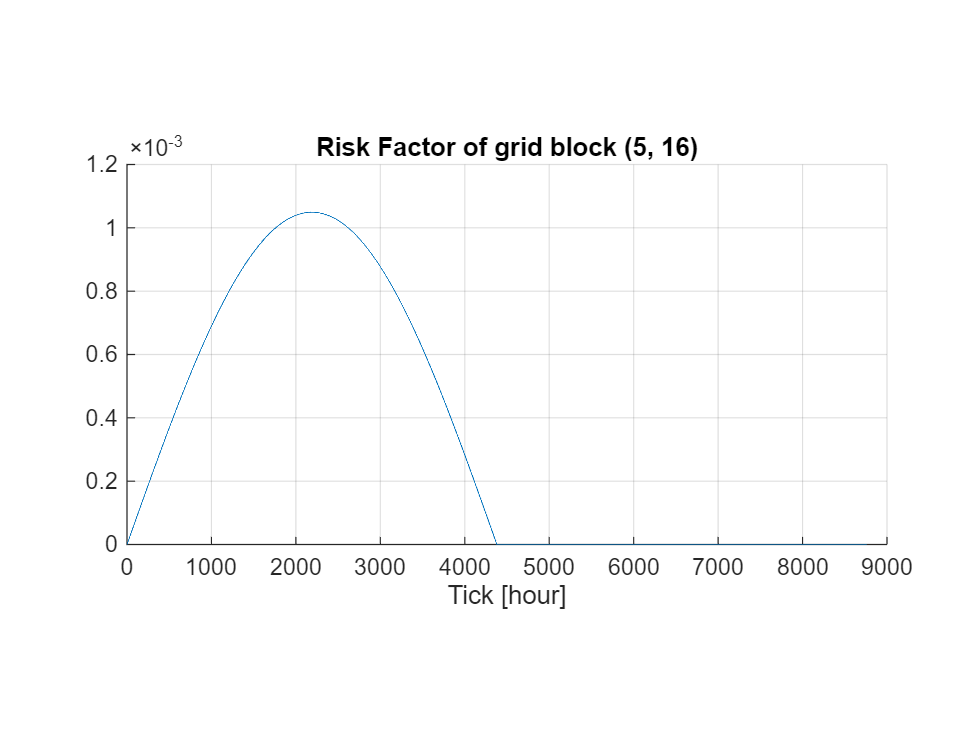

clf; 
hold on; 
grid on; 
plot(tspan, riskFactorPeekaboo); 
xlabel("Tick [hour]"); 
title("Risk Factor of grid block (5, 16)"); 
pbaspect([2 1 1]); 
hold off; 

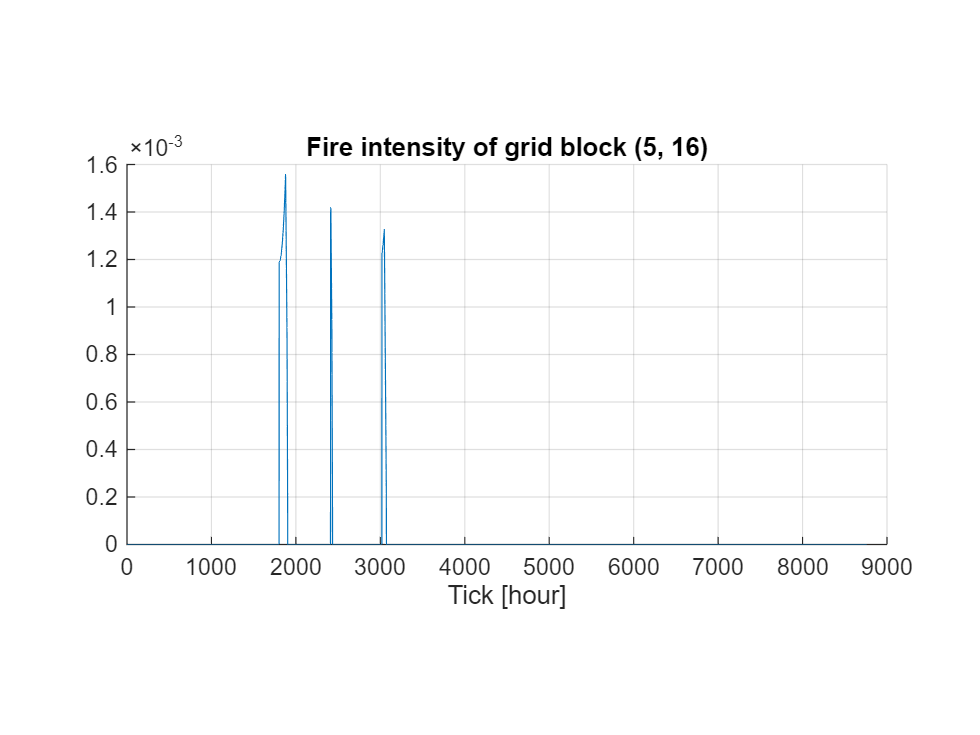

clf; 
hold on; 
grid on; 
plot(tspan, fireIntensityPeekaboo); 
xlabel("Tick [hour]"); 
title("Fire intensity of grid block (5, 16)"); 
pbaspect([2 1 1]); 
hold off; 

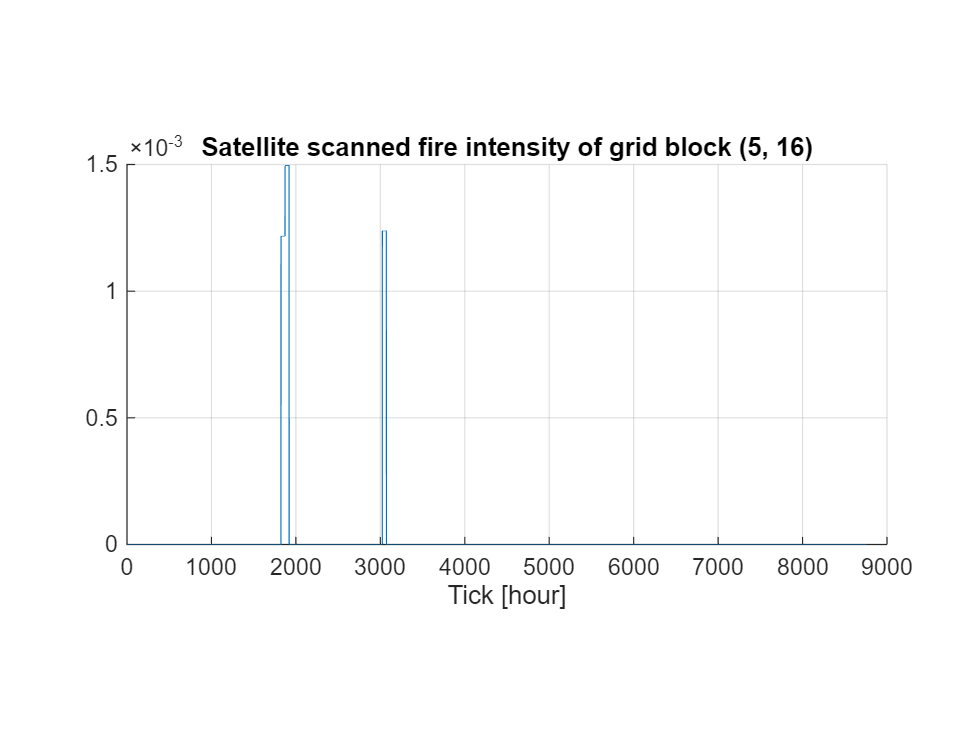

clf; 
hold on; 
grid on; 
plot(tspan, scannedFireIntensitiesPeekaboo); 
xlabel("Tick [hour]"); 
title("Satellite scanned fire intensity of grid block (5, 16)"); 
pbaspect([2 1 1]); 
hold off; 

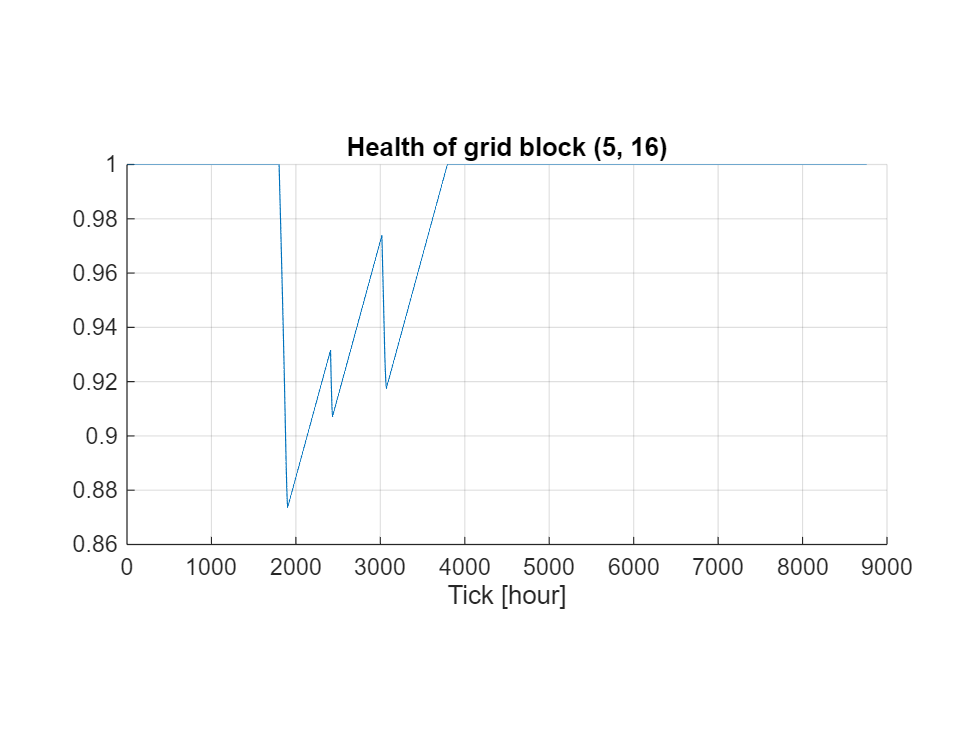

clf; 
hold on; 
grid on; 
plot(tspan, healthPeekaboo); 
xlabel("Tick [hour]"); 
title("Health of grid block (5, 16)"); 
pbaspect([2 1 1]); 
hold off; 

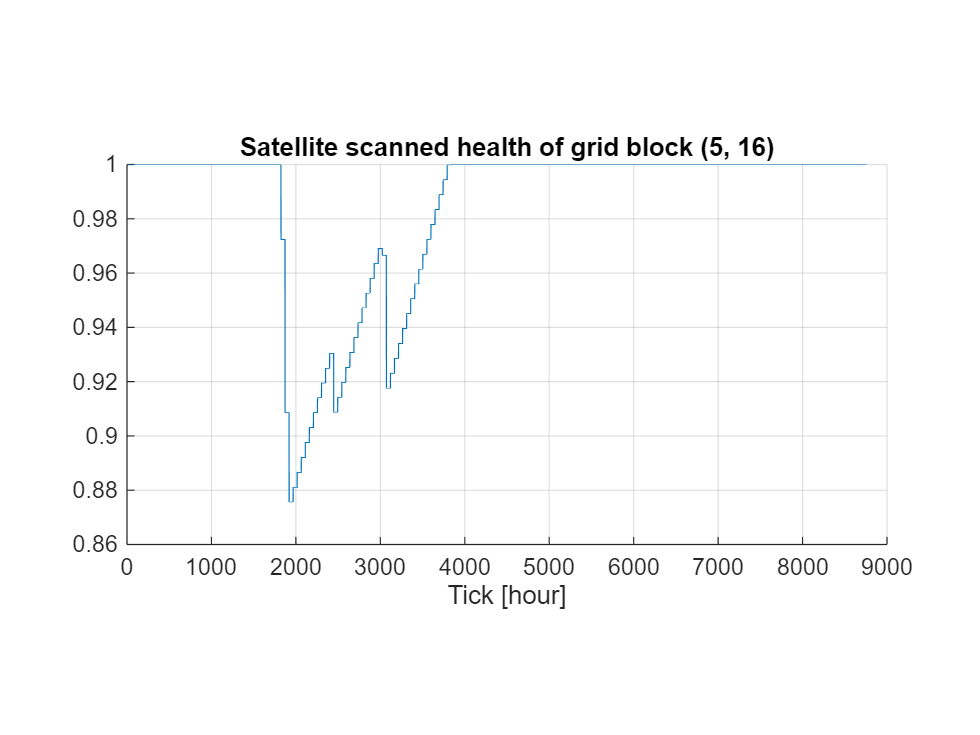

clf; 
hold on; 
grid on; 
plot(tspan, scannedGridHealthPeekaboo); 
xlabel("Tick [hour]"); 
title("Satellite scanned health of grid block (5, 16)"); 
pbaspect([2 1 1]); 
hold off; 

% Units of billions. 
simGrid.totalCosts/1E9

ans = 2.1516e+04